clear;
clc;

I = imread("suppersmall.png");

Q = 2;
[code1, code2, code3] = jpegENCO(I, Q);

key = round(rand(1, 10000000));

te0 = code1;

for i = 1: max([length(code1), length(code2), length(code3)])
    if i <= length(code1)
        bit = code1(i) - 48;
        bit = xor(bit, key(i));
        code1(i) = bit + 48;
    end
    if i <= length(code2)
        bit = code2(i) - 48;
        bit = xor(bit, key(i));
        code2(i) = bit + 48;
    end
    if i <= length(code3)
        bit = code3(i) - 48;
        bit = xor(bit, key(i));
        code3(i) = bit + 48;
    end
end

te = code1;
[row, col, ~] = size(I);
disp((length(code1) + length(code2) + length(code3)) / (row * col * 3 * 8));

    0.2897



r1 = char(zeros(1, 10000000));
r2 = char(zeros(1, 10000000));
r3 = char(zeros(1, 10000000));

N = 16;
K = 11;

head = 1;
cursor1 = 1;
while(head <= length(code1))
    tail = min(head + K - 1, length(code1));
    len = tail - head + 1;
    code = code1(head: tail);
    if len < K
        code = [code 48 * ones(1, K - len)];
    end
    code = HammingENCO(code);
    code = char(code + 48);
    r1(cursor1: cursor1 + N - 1) = code;
    cursor1 = cursor1 + N;
    head = tail + 1;
end

head = 1;
cursor2 = 1;
while(head <= length(code2))
    tail = min(head + K - 1, length(code2));
    len = tail - head + 1;
    code = code2(head: tail);
    if len < K
        code = [code 48 * ones(1, K - len)];
    end
    code = HammingENCO(code);
    code = char(code + 48);
    r2(cursor2: cursor2 + N - 1) = code;
    cursor2 = cursor2 + N;
    head = tail + 1;
end

head = 1;
cursor3 = 1;
while(head <= length(code3))
    tail = min(head + K - 1, length(code3));
    len = tail - head + 1;
    code = code3(head: tail);
    if len < K
        code = [code 48 * ones(1, K - len)];
    end
    code = HammingENCO(code);
    code = char(code + 48);
    r3(cursor3: cursor3 + N - 1) = code;
    cursor3 = cursor3 + N;
    head = tail + 1;
end

te2 = r1;

p1 = char(zeros(1, cursor1 - 1));
p2 = char(zeros(1, cursor2 - 1));
p3 = char(zeros(1, cursor3 - 1));

block = length(p1) / N;
for i = 1: length(p1)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    p1(i) = r1(k + N * j);
end

block = length(p2) / N;
for i = 1: length(p2)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    p2(i) = r2(k + N * j);
end

block = length(p3) / N;
for i = 1: length(p3)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    p3(i) = r3(k + N * j);
end

block = N;
l = length(p1) / N;
for i = 1: length(p1)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    r1(i) = p1(k + l * j);
end

l = length(p2) / N;
for i = 1: length(p2)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    r2(i) = p2(k + l * j);
end

l = length(p3) / N;
for i = 1: length(p3)
    j = int32(mod(i - 1, block));
    k = int32(floor((i - 1)/ block) + 1);
    r3(i) = p3(k + l * j);
end

te3 = r1;

code1 = char(zeros(1, 10000000));
code2 = char(zeros(1, 10000000));
code3 = char(zeros(1, 10000000));

head = 1;
cursor1 = 1;
while(head <= length(p1))
    tail = min(head + N - 1, length(p1));
    len = tail - head + 1;
    code = r1(head: tail);
    code = HammingDECO(code);
    code1(cursor1: cursor1 + K - 1) = code;
    cursor1 = cursor1 + K;
    head = tail + 1;
end

head = 1;
cursor2 = 1;
while(head <= length(p2))
    tail = min(head + N - 1, length(p2));
    len = tail - head + 1;
    code = r2(head: tail);
    code = HammingDECO(code);
    code2(cursor2: cursor2 + K - 1) = code;
    cursor2 = cursor2 + K;
    head = tail + 1;
end

head = 1;
cursor3 = 1;
while(head <= length(p3))
    tail = min(head + N - 1, length(p3));
    len = tail - head + 1;
    code = r3(head: tail);
    code = HammingDECO(code);
    code3(cursor3: cursor3 + K - 1) = code;
    cursor3 = cursor3 + K;
    head = tail + 1;
end

code1 = code1(1: cursor1 - 1);
code2 = code2(1: cursor2 - 1);
code3 = code3(1: cursor3 - 1);

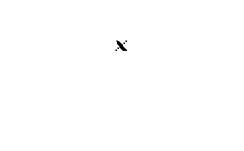

for i = 1: max([length(code1), length(code2), length(code3)])
    if i <= length(code1)
        bit = code1(i) - 48;
        bit = xor(bit, key(i));
        code1(i) = bit + 48;
    end
    if i <= length(code2)
        bit = code2(i) - 48;
        bit = xor(bit, key(i));
        code2(i) = bit + 48;
    end
    if i <= length(code3)
        bit = code3(i) - 48;
        bit = xor(bit, key(i));
        code3(i) = bit + 48;
    end
end

out = uint8(jpegDECO(code1, code2, code3, Q));

figure;
imshow(I);

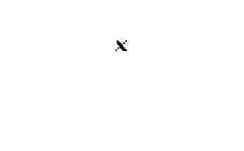

figure;
imshow(out);

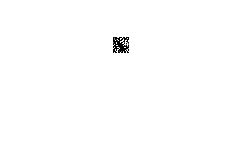

figure;
imshow((I - out(1: row, 1: col)) .^ 2);